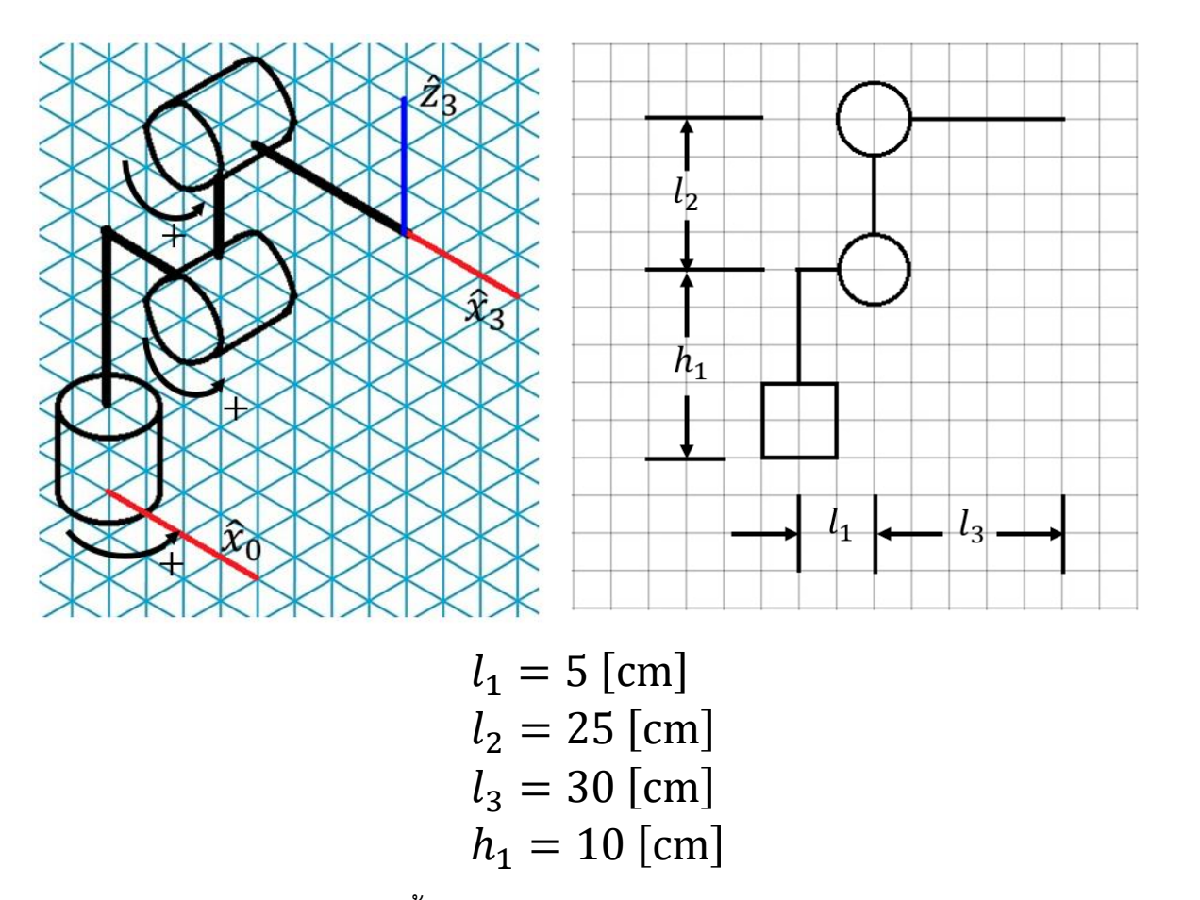                                                                                                                                                                                                                                

**input**

    .txt:    robot command = (2,n)

    .txt:    via_point_info = (3,m) // m = size of command via_points_task set in task space

**local variable**

    command = (1,n) L:0,J:1 

    via_point_task = (3,n) 

    via_point_joint_all = (3,n,4)

    via_point_joint = (3,n)

**step(function)**

readVariable => task2jointConversion =>  select optimal joint => gen C

**readVariable:** write .txt + return: via_point_task = (3,n), command = (1,n) L:0,J:1 

      Description: read variable

**task2jointConversion:** return alert 0: cant access, 1: accessable; via_point_joint (3x4xn) D2: possible joint, D3: No. input via_point task

      Description: check possible access + convert task to joint

**optimalPath: **return selected_via_point_joint (3xn)

**coefficientGen: **return set of C, t_i, and tau

[command,via_point_task] = readVariable('robot_command_v0.txt','via_points_info_v0.txt');
[via_point_joint,flag] = inverseKine(via_point_task(:,1))

via_point_joint =          0         0   -3.1416   -3.1416
   -1.7521         0    0.4148    1.6096
    3.1416         0    2.6561    0.4855


flag =      1     1     1     1


p = forwardKine(via_point_joint)

p =     0.3500    0.3500    0.3500    0.3500
         0         0   -0.0000   -0.0000
    0.3500    0.3500    0.3500    0.3500
